**Loading Data from text File**

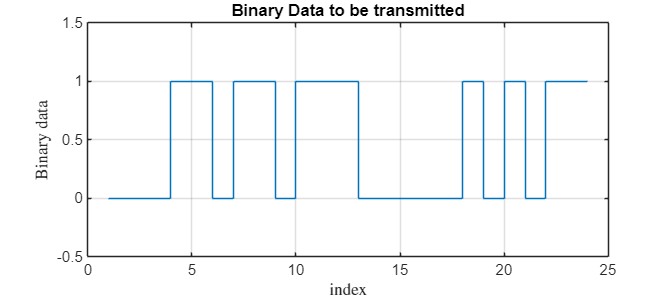

clear all 
close all

tx = transceiver(); % define class

%%% CHANGE PATH TO THE PATH OF TEXT FILE %%%
data = tx.load_data_from_file('F:\backup\commsys\sims\input.txt');  % load data

%plot data
stairs(data); grid on;
xlabel("index","interpreter","latex"); ylabel("Binary data","interpreter","latex");ylim ([-0.5 1.5]); title("Binary Data to be transmitted"); tx.fix_plot_dim(250)

**Modulation**

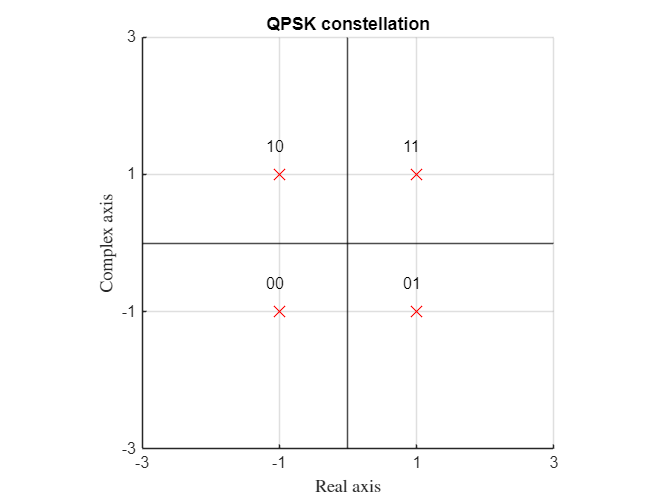


modulation_type = "QPSK";  % QAM or PAM or QPSK
num_bits = 4;              % always 2 for QPSK and even power of 2 for QAM

% visualising modulation constellation
close all
tx.display_modulation(modulation_type, num_bits); 

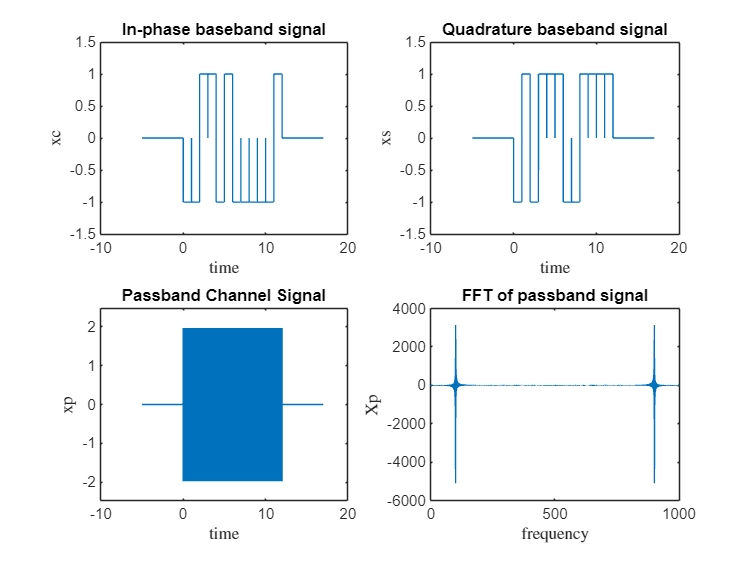

Fs = 1000;     %%%%%% SAMPLING FREQUENCY %%%%%% 
T = 1;         %%%%%% SYMBOL RATE        %%%%%%    
fc = Fs/10;    %%%%%% BANDPASS FREQUENCY %%%%%%  

sp = tx.modulation(data, modulation_type, num_bits, Fs, T, fc);
close 
figure('Position', [100, 100, 1600, 1200]);  % [left, bottom, width, height]

subplot(2, 2, 1)
plot(tx.t, tx.sc)
xlabel("time","interpreter","latex"); ylabel("xc","interpreter","latex");ylim ([min(min(tx.sc),min(tx.ss))-0.5 max(max(tx.sc),max(tx.ss))+0.5]); title("In-phase baseband signal");
subplot(2, 2, 2)
plot(tx.t, tx.ss)
xlabel("time","interpreter","latex"); ylabel("xs","interpreter","latex");ylim ([min(min(tx.sc),min(tx.ss))-0.5 max(max(tx.sc),max(tx.ss))+0.5]); title("Quadrature baseband signal"); 
subplot(2, 2, 3)
plot(tx.t, sp)
xlabel("time","interpreter","latex"); ylabel("xp","interpreter","latex");ylim ([min(sp)-0.5 max(sp)+0.5]); title("Passband Channel Signal"); 
subplot(2, 2, 4)
[f, X] = tx.calc_fft(sp, Fs);
plot(f, real(X))
xlabel("frequency","interpreter","latex"); ylabel("Xp","interpreter","latex"); title("FFT of passband signal"); 

Noise addition

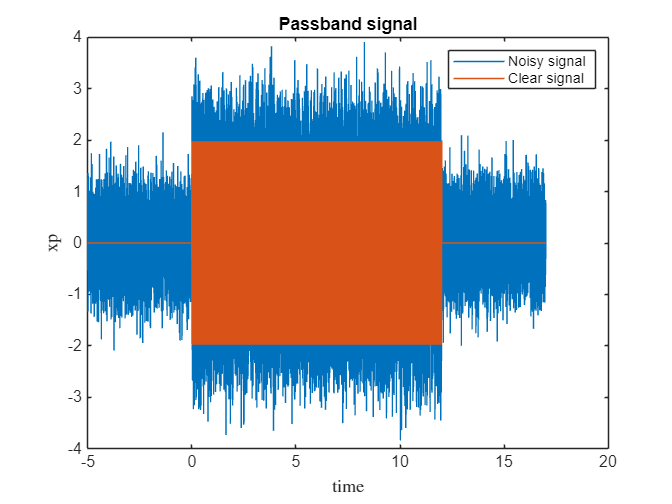

close 

% add white Gaussian noise to the passband signal
sp_noise = tx.add_noise(sp, 5);
plot(tx.t, sp_noise, 'DisplayName', 'Noisy signal');
hold on;
plot(tx.t, sp, 'DisplayName', 'Clear signal');
xlabel("time","interpreter","latex"); ylabel("xp","interpreter","latex"); title("Passband signal"); legend();

**Demodulation**

Calculate received symbol amplitudes

close 

r = tx.demodulation(sp_noise, 'correlator')  % lowpass (or) matched (or) correlator

r =    -1.0197   -0.9777    1.0175    0.9914   -0.9542    1.0164   -1.0024   -0.9991   -1.0050   -1.0139   -0.9998    1.0052   -0.0146    0.0080    0.0052    0.0371    0.0030
   -0.9961    0.9811   -0.9924    0.9860    1.0109    0.9815   -1.0007   -0.9858    1.0093    0.9948    1.0096    1.0047   -0.0161   -0.0278    0.0057    0.0099   -0.0118


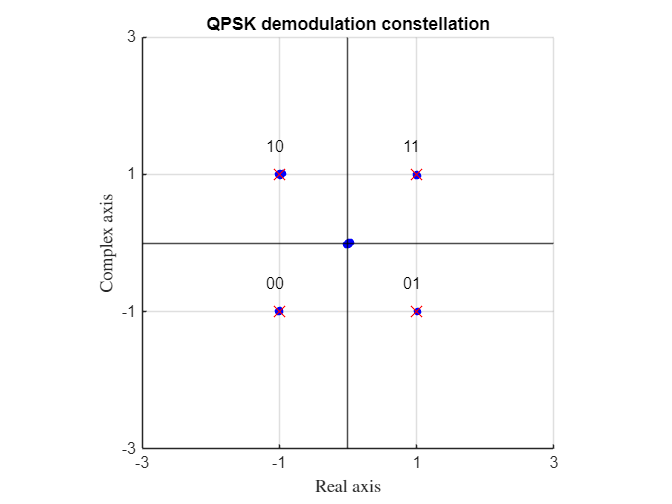

close
tx.demodulation_constellation(r);

**Retreive binary data**

d = tx.get_binary_sequence(r)

d =      0     0     0     1     1     0     1     1     0     1     1     1     0     0     0     0     0     1     0     1     0     1     1     1     0     0     1     0     1     1     1     1     1     0


disp(data)

     0     0     0     1     1     0     1     1     0     1     1     1     0     0     0     0     0     1     0     1     0     1     1     1



Calculate transmission accuracy

N = length(data);
err = 0;
for i = 1:N
    if d(i)~=data(i)
        err = err+1;
    end
end

fprintf("Bit Error percentage = %d%%", round(100*(err/N)))

Bit Error percentage = 0%